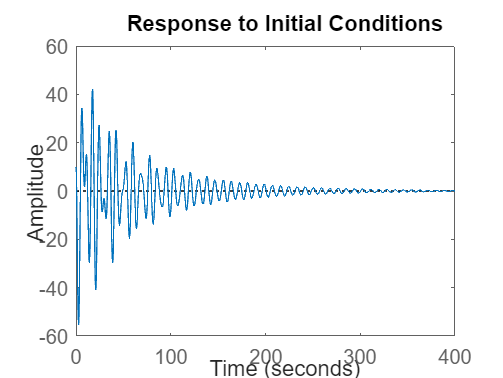

% Importing variables from source
InitState = [8,0,16,0,24,0,0,0,0,0,0,0];

% Implementing LQR Controller to compute GainMatrix
[GainMatrix] = lqr(A,B,Q,R);

% Defining process noise (as per lecture notes)
ProcNoise = diag([0.5, 0.5, 0.5, 0.5, 0.5, 0.5]);

% Defining measurement noise (as per lecture notes)
MeasNoise = 1; 

% Gain matrix for Kalman Filter using output vectors C1, C2, C3
KalmanFilterGain = lqr(A', C1', ProcNoise, MeasNoise)';  

% Simulation of System_1
ModifiedSystem = ss([(A-B*GainMatrix) B*GainMatrix; zeros(size(A)) (A-KalmanFilterGain*C1)], [B;zeros(size(B))],[C1 zeros(size(C1))], D);
figure
initial(ModifiedSystem,InitState)

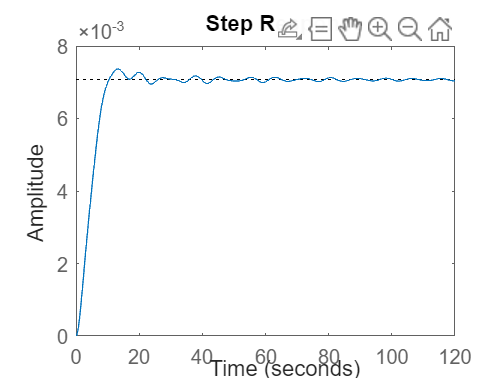

figure
step(ModifiedSystem)

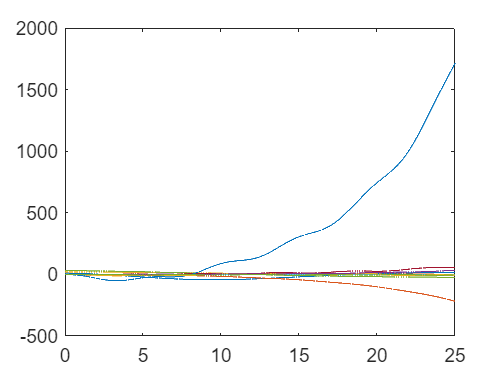


% LQG for a non-linear system
InitState_NonLinear = [10,0,20,0,30,0,0,0,0,0,0,0];
TimeRange = 0:0.01:25;
[T1,Y1] = ode45(@nonLinearLQG,TimeRange,InitState_NonLinear);
plot(T1,Y1)

function StateDerivative = nonLinearLQG(T1,X)
% Crane Mass
CraneMass= 1000;
% Load masses
LoadMass1= 100; 
LoadMass2= 100;
% Cable lengths
CableLength1= 20; 
CableLength2= 10;
% Gravity
Gravity= 9.81;

% System matrices A and B
SysA=[0 1 0 0 0 0;
0 0 -(LoadMass1*Gravity)/CraneMass 0 -(LoadMass2*Gravity)/CraneMass 0;
0 0 0 1 0 0;
0 0 -((CraneMass+LoadMass1)*Gravity)/(CraneMass*CableLength1) 0 -(LoadMass2*Gravity)/(CraneMass*CableLength1) 0;
0 0 0 0 0 1;
0 0 -(LoadMass1*Gravity)/(CraneMass*CableLength2) 0 -(Gravity*(CraneMass+LoadMass2))/(CraneMass*CableLength2) 0];

SysB=[0; 1/CraneMass; 0; 1/(CraneMass*CableLength1); 0; 1/(CraneMass*CableLength2)];

% Cost function parameters
CostQ = diag([50, 100, 150, 200, 250, 300]);
CostR = 0.0025;

% Output vector for first output - x(t)
OutputVec1 = [3 0 0 0 0 0]; 
% Assuming zero D matrix
DMatrix = 0; 

% Computing LQR Gain
LQRGain = lqr(SysA,SysB,CostQ,CostR);
Force = - LQRGain*X(1:6);

% Process and measurement noise
ProcNoise = diag([0.5, 0.5, 0.5, 0.5, 0.5, 0.5]);
MeasNoise = 1; 
% Kalman Filter Gain for OutputVec1
KalmanGain =lqr(SysA', OutputVec1', ProcNoise, MeasNoise)';
% Standard Deviation for OutputVec1
StdDev = (SysA-KalmanGain*OutputVec1)*X(7:12);
StateDerivative = zeros(12,1);

% Dynamics equations for the non-linear system
StateDerivative(1) = X(2); 
StateDerivative(2) = (Force-(Gravity/2)*(LoadMass1*sind(2*X(3))+LoadMass2*sind(2*X(5)))-(LoadMass1*CableLength1*(X(4)^2)*sind(X(3)))-(LoadMass2*CableLength2*(X(6)^2)*sind(X(5))))/(CraneMass+LoadMass1*((sind(X(3)))^2)+LoadMass2*((sind(X(5)))^2)); 
StateDerivative(3) = X(4);
StateDerivative(4) = (StateDerivative(2)*cosd(X(3))-Gravity*(sind(X(3))))/CableLength1; 
StateDerivative(5) = X(6);
StateDerivative(6) = (StateDerivative(2)*cosd(X(5))-Gravity*(sind(X(5))))/CableLength2; 
StateDerivative(7) = X(2)-X(10);
StateDerivative(8) = StateDerivative(2)-StdDev(2);
StateDerivative(9) = X(4)-X(11);
StateDerivative(10) = StateDerivative(4)-StdDev(4);
StateDerivative(11) = X(6)-X(12);
StateDerivative(12) = StateDerivative(6)-StdDev(6);
end
